# Calculate GLCMs using Four Different Offsets

Read a grayscale image into the workspace.

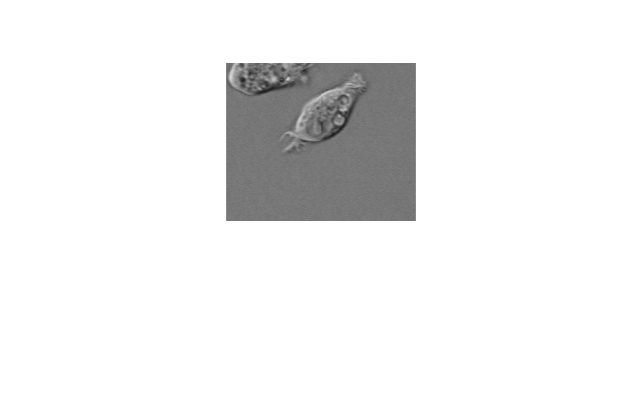

I = imread('cell.tif');
imshow(I)

Define four offsets.

offsets = [0 1; -1 1;-1 0;-1 -1];

Calculate the GLCMs, returning the scaled image as well. Display the scaled image, performing an additional rescaling of data values to the range [0, 1].

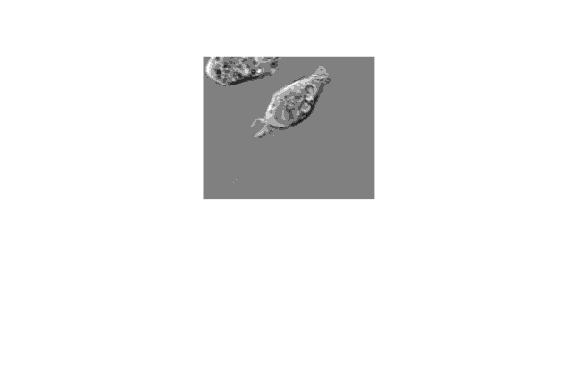

[glcms,SI] = graycomatrix(I,'Offset',offsets);
imshow(rescale(SI))

Note how the function returns an array of four GLCMs.

whos

  Name                     Size                Bytes  Class            Attributes

  I                      159x191               30369  uint8                      
  N1                       1x1                     8  double                     
  N2                       1x1                     8  double                     
  Par_frequency            1x1                     8  double                     
  Par_tiempo               1x1                     8  double                     
  SI                     159x191              242952  double                     
  activity                 1x29761            238088  double                     
  activity_filtrado        1x29761            238088  double                     
  baseline                 1x29761            238088  double                     
  baseline_filtrado        1x29761            238088  double                     
  bp                       1x1                     8  digitalFilter              
  dBtf         

*Copyright 2012 The MathWorks, Inc.*